# **Power_Networkクラスのデータの見方**

    Step１では電力系統モデルを`power_network`クラスとして定義する方法を、Step２では作成した`power_network`クラスに制御器を付加する方法を開設しました。

    ここまでで、電力系統モデルの定義は完了したので、ここで一度`power_network`クラスのデータの読み方について開設します。

    初めに電力システムは「母線(bus)」「機器(component)」「送電線(branch)」に切り分けてそれらで構成されるシステムとして表現できると解説しましたね。（[Main.mlx](matlab:open('./Main.mlx'))）

    GUILDAでは電力ネットワークを各構成要素ごとのオブジェクトの集合として管理します。

    以降の解説ではこのpower_networkクラスを格納した変数をnetとしてコード解説していきます。

net = network.Tutorial3bus;

 
component class：
       Link　　　class tree
 [help], [doc]     component
 [help], [doc]       ┣━ component.GFM.Inverter


# **1.各クラスへのアクセス方法**

**まずは、power_networkクラスから各構成要素へのアクセスする方法を覚えましょう。**

**各クラスをpower_networkへ格納している構造をイメージで示します。**

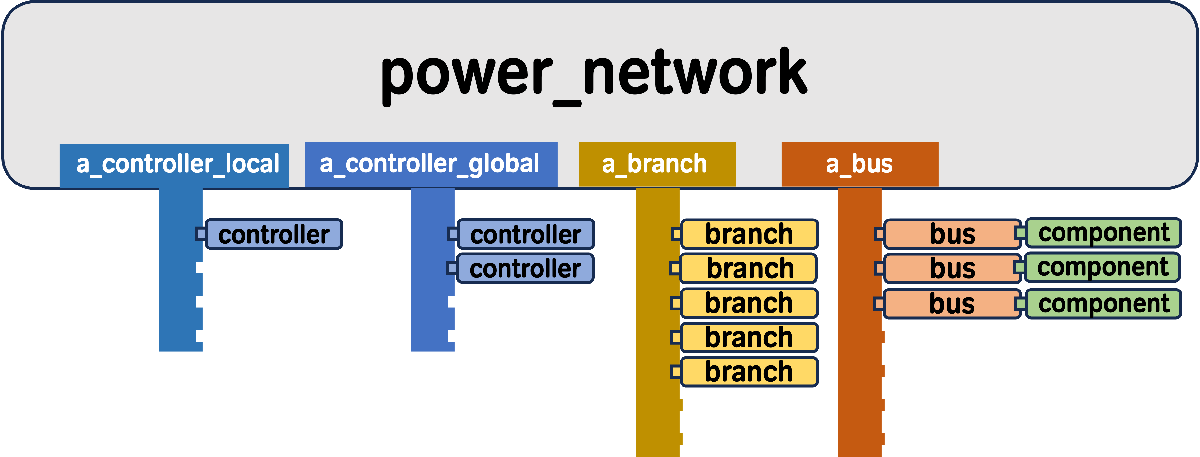

## `Class : branch`

    `branchクラスはpower_networkクラスのa_branchというプロパティにcell配列として格納されています。`

net.a_branch

 
controller class：
       Link　　　class tree
 [help], [doc]     controller
 [help], [doc]       ┣━ controller.broadcast_PI_AGC


    例えば登録したブランチの１つ目のクラスを見たい場合は、以下のように実行します。

branch1 = net.a_branch{1}

## `Class : bus`

    `busクラスはpower_networkクラスのa_busというプロパティにcell配列として格納されています。`

net.a_bus

    例えば登録したブランチの2つ目のクラスを見たい場合は、以下のように実行します。

bus1 = net.a_bus{2}

## `Class : component`

    `上の図に示したようにcomponentクラスはpower_networkクラスに直接格納されている訳ではありません。`

    `全ての機器は各母線に1対1で接続されているとします。機器１というと母線１に接続されている機器のことを指します。`

    `各componentクラスは接続先の母線クラスのcomponentプロパティに格納されています。`

component1 = net.a_bus{1}.component

## `Class : controller`

`制御器のクラスはglobalコントローラとlocalコントローラに分別されて格納されています。`

`それぞれ、power_networkクラスのa_controller_global, a_controller_localにcell配列として格納されています。`

% 制御器を付加
con = controller.broadcast_PI_AGC(net,1:2,1:2,-10,-10);
net.add_controller_global(con)

con1 = net.a_controller_global{1}

# **2 各クラスのプロパティ**

**ここでは各クラスの規定クラスに設定されているプロパティについて紹介します。**

**これらの規定クラスを継承したクラスには、その他のプロパティもあることに注意してください。**

## **Class : power_network**

###     ⅰ. 電力系統を構成する要素の各クラスの保管プロパティ[上述]

- `a_bus`：母線情報のセル配列

- `a_branch`：送電網のセル配列

- `a_controller_global`：グローバルコントローラのセル配列

- `a_controller_local`：ローカルコントローラのセル配列

###     ⅱ.  平衡点・定常潮流状態に関するプロパティ

- `V_equilibrium`：潮流計算によって得られた、各母線の電圧フェーザの平衡点が複素数値で格納された配列

- `I_equilibrium`：潮流計算によって得られた、各母線の電流フェーザの平衡点が複素数値で格納された配列

- `x_equilibrium`：潮流計算で得られた定常潮流状態に対応する各機器の平衡点を機器番号順に積み重ねたベクトル  

- `x0_controller_local`：各ローカルコントローラの平衡点のベクトル

- `x0_controller_global`：各グローバルコントローラの平衡点のベクトル

###     ⅲ. その他のプロパティ 

- `Tag`：識別子。ニックネームみたいなもの

- `omega0`：基準角周波数

- `Edit_Log`：power_networkクラス内の値の変更等のログ（`table`型）

## **Class : bus**

###     ⅰ. 系統を構成するクラスを格納するプロパティ

- `power_network`：母線が接続している系統クラス

- `component`：母線に接続されている機器クラス

###     ⅱ.  平衡点・定常潮流状態に関するプロパティ

- `V_equilibrium`：潮流計算によって得られた、その母線の電圧フェーザの複素数値

- `I_equilibrium`：潮流計算によって得られた、その母線の電流フェーザの複素数値

###     ⅲ. その他のプロパティ 

- `Tag`：識別子。ニックネームみたいなもの

- `index`：母線番号

- `shunt`：シャント値（母線と地面間のアドミタンス値と考えれば良いと思います。）

- `Edit_Log`：busクラス配下のプロパティの変更等のログ（`table`型）

- `CostFunction`：コスト関数（ここに決められた型の関数ハンドルを設定するとシミュレーション結果にコスト関数のデータも出力されるようになる）

- `GraphCoordinaten`：グラフ上の座標（ネットワーク構造をグラフ化す際に使用する座標の値を格納するプロパティ）

busクラスは基本的に「PV bus」「PQ bus」「slack bus」の３種類があります。

これらのクラスはbusクラスを継承した子クラスとして定義されています。詳細については[Bus_variety.mlx](matlab:open('./ClassManual/Bus_variety.mlx'))を参照してください。

## **Class : branch**

###     ⅰ. 系統を構成するクラスを格納するプロパティ

- `network`：送電線が接続している系統クラス

###     ⅱ.  送電線が接続する母線に関する情報

- `from,to`：送電線が接続する２つの母線のインデックス

- `bus_from,bus_to`：送電線が接続する２つの母線のbusクラス

###     ⅲ. その他のプロパティ 

- `Tag`：識別子。ニックネームみたいなもの

- `index`：送電線番号

- `Edit_Log`：branchクラス配下のプロパティの変更等のログ（`table`型）

- `parallel`：シミュレーションにおいて送電線を解列/並列させる際に使用する`flag`

- `grid_code`：グリッドコードを関数ハンドルとして定義

- `CostFunction`：コスト関数（ここに決められた型の関数ハンドルを設定するとシミュレーション結果にコスト関数のデータも出力されるようになる）

 GUILDAではbranchクラスとして「π型等価回路」「変圧位相調整器付きπ型等価回路」「T型等価回路」の３種類が用意されています。

これらのクラスはbranchクラスを継承した子クラスとして定義されています。詳細については[Branch_variety.mlx](matlab:open('./ClassManual/Branch_variety.mlx'))を参照してください。

## **Class : component**

###     ⅰ. 系統を構成するクラスを格納するプロパティ

- connected_bus：機器が接続している母線クラス

###     ⅱ.  平衡点・定常潮流状態に関するプロパティ

- `x_equilibrium`：定常潮流状態に対応する機器の平衡点

- `u_equilibrium`：定常潮流状態に対応する機器への定常入力値

- `V_equilibrium`：接続母線の定常潮流状態における電圧フェーザの複素数値

- `I_equilibrium`：接続母線の定常潮流状態における電流フェーザの複素数値

- `system_matrix`：上の平衡点近傍における近似線形システムのシステム行列

###     ⅲ. simulationに関わるプロパティ 

- InputType：シミュレーションにおいて外部入力の方法を指定。

- `parallel`：シミュレーションにおいて機器を解列/並列させる際に使用する`flag`

- `grid_code`：グリッドコードを関数ハンドルとして定義

- `CostFunction`：コスト関数（ここに決められた型の関数ハンドルを設定するとシミュレーション結果にコスト関数のデータも出力されるようになる）

- `get_dx_con_func, u_func`：simulationの開始時に各システムのダイナミクスを関数ハンドルとしてこのプロパティにセットする。

###     ⅲ. その他のプロパティ 

- `Tag`：識別子。ニックネームみたいなもの

- `index`：機器番号（接続母線の番号）

- `parameter`：機器のパラメータをtable型で格納

- `Edit_Log`：componentクラス配下のプロパティの変更等のログ（`table`型）

- `GraphCoordinaten`：グラフ上の座標（ネットワーク構造をグラフ化す際に使用する座標の値を格納するプロパティ）

GUILDAでは、機器モデルとしてcomponentクラスを継承したクラスが各種あります。

各モデルの詳細は以下を参照のこと

class_dictionary component;

## **Class : controller**

###     ⅰ. 系統を構成するクラスを格納するプロパティ

- network：接続している系統クラス

###     ⅱ. 制御器の入力対象・観測対象に関するプロパティ

- a_component_input：入力対象の機器のcomponentクラスのリスト

- a_component_observe：観測対象の機器のcomponentクラスのリスト

###     ⅱ.  平衡点・定常潮流状態に関するプロパティ

- `system_matrix`：上の平衡点近傍における近似線形システムのシステム行列

###     ⅲ. simulationに関わるプロパティ 

- `connected_index_input`：入力対象の機器のうち並列中の機器の番号リスト

- `connected_index_observe`：観測対象の機器のうち並列中の機器の番号リスト

- `port_input`：入力対象の機器のどの入力ポートと接続するかを指定

- `port_observe`：観測対象の機器のどの入力ポートと接続するかを指定

- `parallel`：シミュレーションにおいて制御器を解列/並列させる際に使用する`flag`

- `grid_code`：グリッドコードを関数ハンドルとして定義

- `CostFunction`：コスト関数（ここに決められた型の関数ハンドルを設定するとシミュレーション結果にコスト関数のデータも出力されるようになる）

- `get_dx_u_func`：simulationの開始時に各システムのダイナミクスを関数ハンドルとしてこのプロパティにセットする。

###     ⅲ. その他のプロパティ 

- `Tag`：識別子。ニックネームみたいなもの

- `index`：制御器番号

- `parameter`：制御器のパラメータをtable型で格納

- `Edit_Log`：controllerクラス配下のプロパティの変更等のログ（`table`型）

GUILDAでは、制御器モデルとしてcontrollerクラスを継承したクラスが各種あります。

各モデルの詳細は以下を参照のこと

class_dictionary controller;

[](matlab:open('./Step2_AddController.mlx'))　　[](matlab:open('./Step4_SimulateCondition.mlx'))